# PROJECT 5

TYLOR COOKS, 026538081

**PART 1**

IDFT:

Takes frequency domain signal and converts it to time domain.Each subcarrier in the OFDM signal is modulated,

DFT: 

The DFT i used for recovering transmitted data in OFDM systems and it allows the receiver to  separate the overlapped subcarriers due to their orthogonality property

Number of subcarriers: 256

subcarrier Spacing: 64

**PART 2:**

QPSK, 8-PSK, and 16-PSK exhibit progressively higher bit error rates (BER), respectively. This is because all these modulation schemes use the same data symbol energy level, meaning the circle's radius that represents them on a constellation plot remains constant. However, as the number of points on this circle increases with each scheme, the points become more closely spaced. This proximity makes it more likely for the receiver to confuse one symbol for another, which results in a higher BER. To achieve a lower BER with more complex M-PSK schemes, increasing the signal energy.

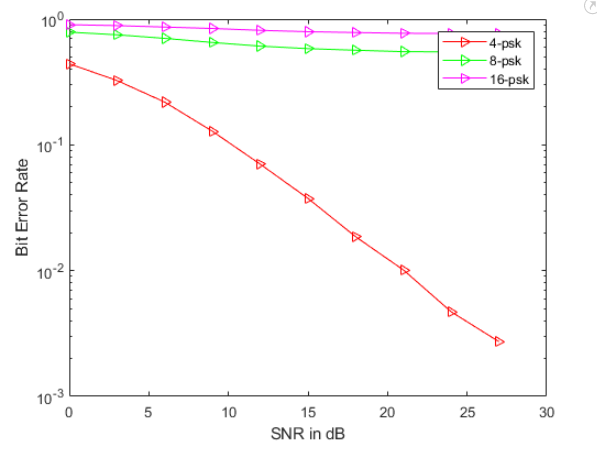

**PART 3:**

There is no explicit representation of a Digital-to-Analog Converter (DAC) or an Analog-to-Digital Converter (ADC).

The closest representation to Digital to analog is the output from the IFFT block (`TrDataIfft`) , which is treated as if it were already in an analog form

 In addition to, the  `filter(h,1,TrDataIfftGi)` function simulates the effect of the channel on the transmitted signal as if it were analog.

Also for the ADC, the `TxDataIfftGiNoise `is sent to the FFT block without being converted from analog to digital. This program assumes that the signal is ready to be processed 

without the ADC OR DAC .  

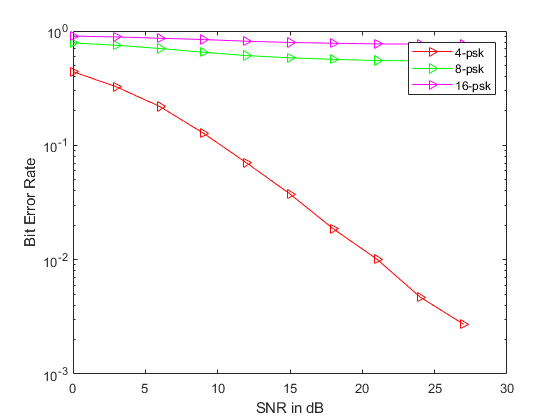

% in this Mfile, I want to investigate the performance of LSE algorithm in
% OFDM channel estimation
%
% for further information see the 
%       [Xiaodong Cai and Georgios B. Giannakis,
%        “Error Probability Minimizing Pilots for
%        OFDM with M-PSK Modulation over Rayliegh-Fading
%        Channels,” IEEE Transactions on Vehicular 
%        technology, vol. 53, No. 1, pp 146-155, Jan. 2004.]


% initialize 
    clear
    clc


% parameter definition
    N  = 256;           % total number of subchannels
    P  = 256/8;         % total number of Pilots
    S  = N-P;           % totla number of data subchannels
    GI = N/4;           % guard interval length
    Mod  = [4 8 16];             % modulation
    pilotInterval = 8;  % pilot position interval
    L  = 16;            % channel length
    nIteration = 500;    % number of iteration in each evaluation

    SNR_V = [0:3:27];   % signal to noise ratio vector in dB
    ber = zeros(1,length(SNR_V));   % initializing bit error rate

% Pilot Location and strength
    Ip = [1:pilotInterval:N];       % location of pilots
    Is = setxor(1:N,Ip);            % location of data
    
    Ep = 2;                        % energy in pilot symbols in comparison 
                                    % to energy in data symbols

% fft matrix
    F = exp(2*pi*sqrt(-1)/N .* meshgrid([0:N-1],[0:N-1])...
        .* repmat([0:N-1]',[1,N]));

for M = Mod
    for( i = 1 : length(SNR_V))
    SNR = SNR_V(i);
        for(k = 1 : nIteration)
            % generating random channel coefficients
                h(1:L,1)  =     random('Normal',0,1,L,1) + ...
                            j * random('Normal',0,1,L,1);  
                h  = h./sum(abs(h));    % normalization    
            
            % Tr Data
                TrDataBit = randi(M,N,1) -1;
                TrDataMod = qammod(TrDataBit,M);
                TrDataMod(Ip) = Ep * TrDataMod(Ip);
                TrDataIfft = ifft(TrDataMod,N);
                TrDataIfftGi = [TrDataIfft(N- GI + 1 : N);TrDataIfft];
    
            % tx Data    
                TxDataIfftGi = filter(h,1,TrDataIfftGi);    % channel effect
                % adding awgn noise
                TxDataIfftGiNoise = awgn(TxDataIfftGi ...
                    , SNR - db(std(TxDataIfftGi))); % normalization to signal power
    
                TxDataIfft  = TxDataIfftGiNoise(GI+1:N+GI);
                TxDataMod   = fft(TxDataIfft,N);
    
                % Channel estimation
                Spilot = TrDataMod(Ip); % trnasmitted pilots
                Ypilot = TxDataMod(Ip); % received pilots
    
                G = (Ep * length(Ip))^-1 ...
                    * ctranspose(sqrt(Ep)*diag(Spilot)*ctranspose(F(1:L,Ip)));
    
                hHat = G*Ypilot;    % estimated channel coefficient in time domain
    
                TxDataBit   = qamdemod(TxDataMod./(fft(hHat,N)),M);
    
            % bit error rate computation
                [nErr bErr(i,k)] = symerr(TxDataBit(Is),TrDataBit(Is));
        end
    end


    if M == 4
        qpsk = bErr;
    elseif M == 8
        psk8_ber = bErr;
    elseif M == 16
        psk16_ber = bErr;
    end
end
f1 = figure(1);
    set(f1,'color',[1 1 1]);
    semilogy(SNR_V,mean(qpsk'),'r->',"DisplayName",'4-psk')
    hold on 
    semilogy(SNR_V,mean(psk8_ber'),'g->',"DisplayName",'8-psk')
    semilogy(SNR_V,mean(psk16_ber'),'m->',"DisplayName",'16-psk')
    xlabel('SNR in dB');
    ylabel('Bit Error Rate')
    legend
    hold off